%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%  EC516 Project 01  %%%
%%% Jeremiah Sullivan  %%%
%%%    ML, IC, or RL   %%% 
%%%   November 2018    %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Project Requirements
% (a)	Record and display a speech signal
% (b)	(3 points) Compute and display the discrete TDFT of the	
%           rectangular	(“box”)	window, duration ~20 ms.


% (c)	(4 points) Use GFBS Method to compute signal back from discrete TDFT
clc; clear all; close all;

## A: Record and display signal

Traditionally sample rate is set by analog (or physical) low-pass filters

Choosing to use 2013 13" Macbook Pro as a recording platform of convenience. Using this analog platform produces a few unknowns. No information is available on the type of internal filters preceding the ADC. Thus we will try recordings with permutations of the following parameters:

- Max sample rate allowed by sound-card

- Minimum Sample rate required for speech (~ 8 kHz) 

- Running on battery or AC power

For replicability, let's also generate the sound using Matlab. Let's try an LFM chirp. We now have further unkowns (system record and 

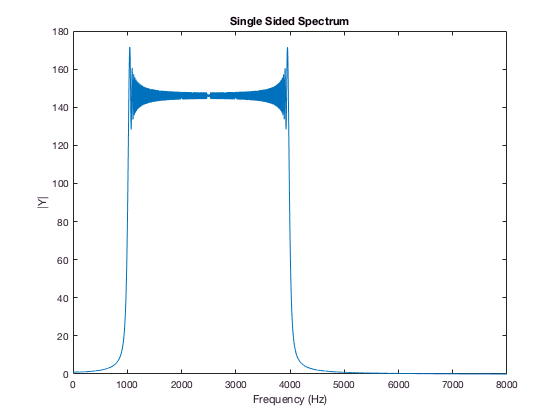

% Max audio-settings, 24-bit, 96 kHz
% Note one speaker on my mac is broken, I believe only a tweeter is functional

% Set up output
signalTime = 1; % second
fVec       = [1000, 4000]; % from 100 Hz to 4 kHz
fSampleOut = 16000;       % Hz
timeArray  = 0:(1/fSampleOut):signalTime; % Time (seconds)
fArray     = linspace(fVec(1), fVec(2), length(timeArray) );  
nBitsOut   = 24; 
y          = chirp(timeArray, fVec(1), timeArray(end), fVec(end)); 
Y = fftshift(abs(fft(y)));
Y = Y(round(length(Y)/2):end); 
f = linspace(0, fSampleOut/2, length(Y)); 
plot(f, Y); xlabel('Frequency (Hz)'); ylabel('|Y|'); title('Single Sided Spectrum'); 

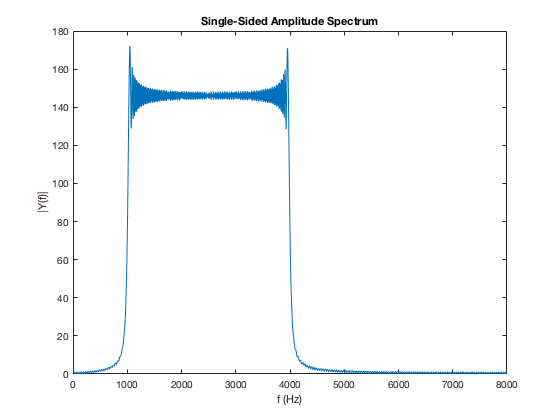

[Y, f] = plotFFT(y, fSampleOut, 2^14); 

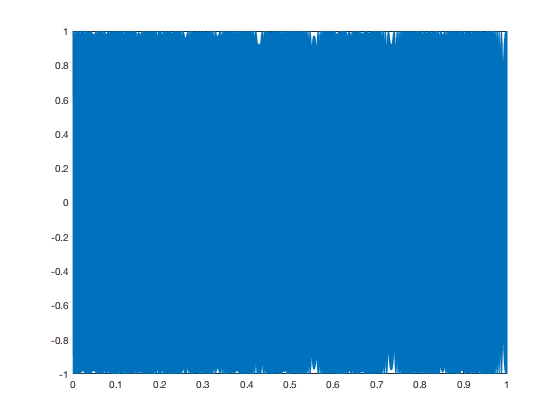

plot(timeArray, y); 

windowLength = 2^12; dftLength = 2^12;
spectrogram(y, fSampleOut, fSampleOut)

Error using welchparse>segment_info (line 220)
The length of the segments cannot be greater than the length of the input signal.

Error in welchparse (line 32)
[L,noverlap,win] = segment_info(M,win,noverlap);

Error in 

ylabel('Frequency (Hz)'); xlabel('Time (s)'); title('Output Signal'); 




